# HomeWork n.1 2021/22

***  Mazza Lorenzo 0124002003***

Calcolate due numeri interi $p$ e $q$  che sono, rispettivamente, il numero di caratteri del vostro nome e il numero di caratteri del vostro  cognome. Usate questi due numeri per creare la seguente funzione:


$$e^{-x} \cdot (cos(\frac {p \cdot x}{2}-\pi/2))^2 +  \frac {q}{1+2x^2}cos(2x)-3$$


Tale funzione è la vostra **funzione di riferimento**. Scegliete un certo intervallo $[a,b]$ in modo che la vostra funzione di riferimento abbia **esattamente** 5 zeri, 2 minimi e 2 massimi in tale intervallo.

**PUNTO 1: definite la function Matlab che implementa la vostra funzione di riferimento e che chiamerete **`funrif`**;**

Essendo il mio nome completo Lorenzo Mazza, il numero intero **p** sarà uguale a 7, mentre il numero intero **q **sarà uguale a 5.

Partendo quindi dalla funzione:


$$e^{-x} \cdot (cos(\frac {p \cdot x}{2}-\pi/2))^2 +  \frac {q}{1+2x^2}cos(2x)-3$$


funrif = @(x) exp(-x).*(cos(7*x/2-pi/2)).^2+(5./(1+2*x.^2).*cos(2*x)-3); %Si inserisce il "punto" prima degli operatori *, /, ^, \ quando si vuole che gli operatori stessi effettuino l'operazione relativa su vettori o matrici, elemento per elemento.

Scritta la mia funzione la visualizzio graficamente:

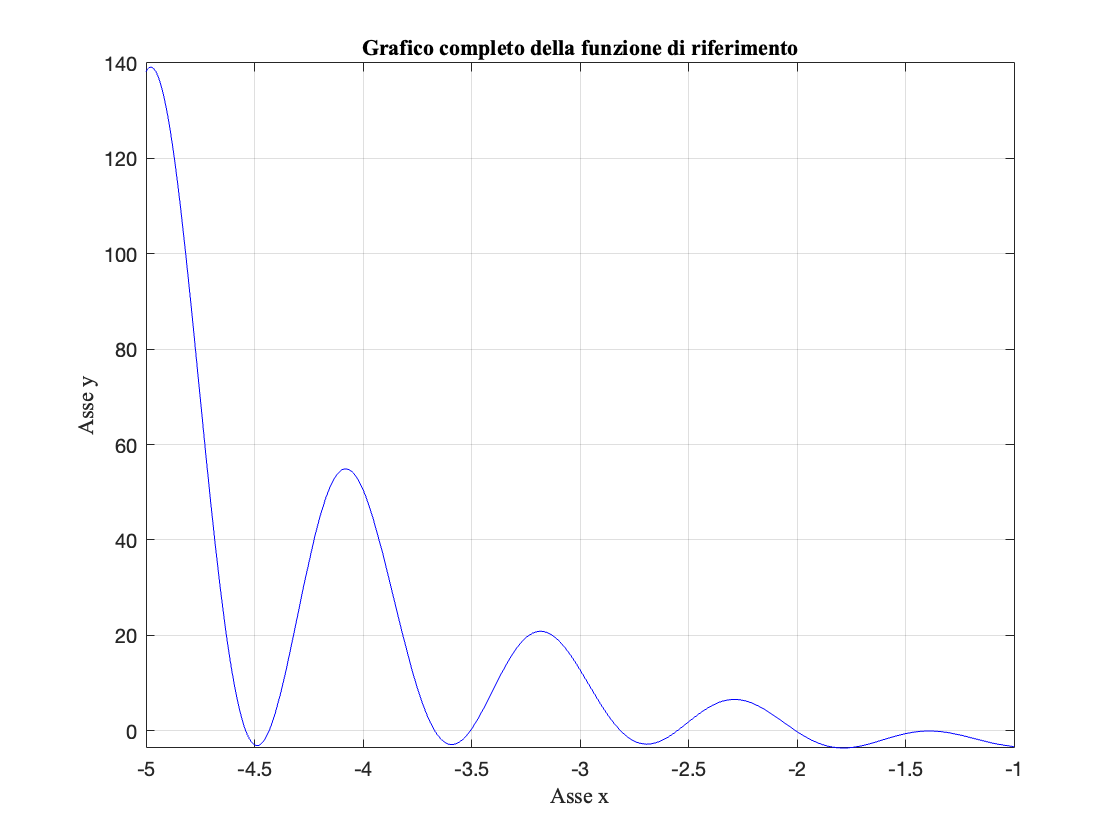

%come richiesto imposto tutti i numeri in formato long (15 cifre dopo la virgola)
format long
%con figure creo le figure, che vanno numerate in maniera crescente a partire da 1
figure(1) 
%con fplot definisco un intervallo della mia funzione, specificando gli estremi
fplot(funrif,[-5,-1],'color','b') 
hold on %hold on mi permette di conservare i grafici negli assi correnti (i nuovi grafici non eliminano quelli già esistenti)
grid on %grid on ci fa visualizzare la griglia 

xlabel("Asse x",'FontName','Times New Roman') %do un nome all'asse x
ylabel("Asse y",'FontName','Times New Roman') %do un nome all'asse y
title("Grafico completo della funzione di riferimento",'FontName','Times New Roman') %do un titolo al mio grafico
hold off

**PUNTO 2: visualizzate il grafico della funzione di riferimento in **$[a,b]$**, specificando espicitamente quale intervallo avete scelto e indicando sul grafico (comando **`text`**) gli estremi dell'intervallo scelto, i 5 zeri, il primo valore minimo e l'ascissa del primo minimo (detta *****punto di minimo 1*****), il secondo valore minimo e l'ascissa del secondo minimo (detta *****punto di minimo 2*****), il primo valore massimo e l'ascissa del primo massimo (detta *****punto di massimo 1*****), il secondo valore massimo e l'ascissa del secondo massimo (detta *****punto di massimo 2*****);**

Visualizzo graficamente la funzione in uno specifico intervallo [a,b] mettendo in evidenza i 5 zeri, il primo punto di minimo, il primo punto di massimo, il secondo punto di minimo ed il secondo punto di massimo:

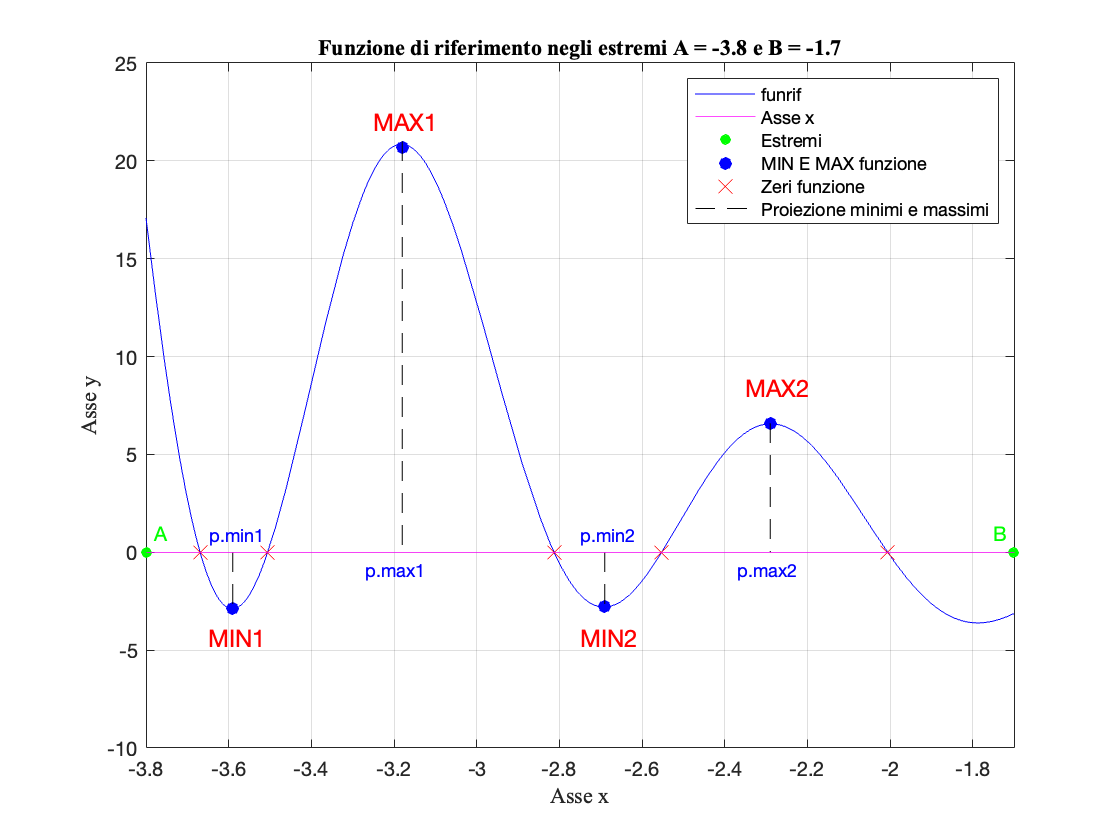

figure(2) %creo seconda figura
a=-3.8; %creo variabile per estremo intervallo sinistro
b=-1.7; %creo variabile per estremo intervallo destro
% Tramite fplot scelgo un intervallo contenente 5 zeri, 2 minimi e 2 massimi
fplot(funrif,[a,b],'color','b')
%tramite il comando axis definisco le coordinate per poter visualizzare un'area precisa del grafico
axis([a b -10 25])
hold on %hold on mi permette di conservare i grafici negli assi correnti (i nuovi grafici non eliminano quelli già esistenti)
grid on %grid on ci fa visualizzare la griglia
xlabel("Asse x",'FontName','Times New Roman') %do nome all'asse x
ylabel("Asse y",'FontName','Times New Roman') %do nome all'asse y
title("Funzione di riferimento negli estremi A = -3.8 e B = -1.7",'FontName','Times New Roman')
yline(0,'-','color','m') %%Evidenzio l'asse delle x (attenzione, si usa yline ma non fa riferimento all'asse y, bensì a quello x)
%evidenzio gli estremi
text(-3.78,1,'A', "Color", 'g', "FontSize",10.0); %aggiunge lettera A all'estremo sinistro
text(-1.75,1,'B', 'color','g', "FontSize",10.0); %aggiunge lettera B all'estremo destro

plot([a,b],[0,0],'o','markersize',5,'color','g','MarkerFaceColor','g') %aggiungo pallino verde per segnare gli estremi

text(-3.65,-4.4, "MIN1","Color",'r',"FontSize",12) %indico (non in maniera precisissima) il primo minimo
text(-2.75,-4.4, "MIN2","Color",'r',"FontSize",12) %indico (non in maniera precisissima) il secondo minimo
text(-3.25,22.0,"MAX1","Color",'r',"FontSize",12) %indico (non in maniera precisissima) il primo massimo
text(-2.35,8.4,"MAX2","Color",'r',"FontSize",12) %indico (non in maniera precisissima) il secondo massimo
plot([-3.59 -2.69 -3.18 -2.29], [-2.87 -2.79 20.7 6.56], 'o','color','b','MarkerFaceColor','b') %Segno minimi e massimi con dei pallini
plot([-3.66919 -3.50524 -2.8125 -2.55219 -2.00538],[0 0 0 0 0],'x','markersize',9,'color','r') % Segno le coordinate degli zeri con una x per poterli visualizzare facilmente
%proietto sia i 2 minimi che i due massimi
plot([-3.59,-3.59], [0,-2.87], '--','color','k')
plot([-3.18,-3.18], [21.0,0], '--','color','k')
plot([-2.69,-2.69], [0,-2.79], '--','color','k')
plot([-2.29,-2.29], [6.59,0], '--','color','k')

text(-3.647,0.9,'p.min1', "Color", 'b',"FontSize",9); %aggiungo una scritta per visualizzare facilmente il primo minimo
text(-3.27,-0.9,'p.max1', "Color", 'b',"FontSize",9); %aggiungo una scritta per visualizzare facilmente il primo massimo
text(-2.75,0.9,'p.min2', "Color", 'b',"FontSize",9); %aggiungo una scritta per visualizzare facilmente il secondo minimo
text(-2.37,-0.9,'p.max2', "Color", 'b',"FontSize",9); %aggiungo una scritta per visualizzare facilmente il secondo massimo


legend('funrif','Asse x','Estremi','MIN E MAX funzione','Zeri funzione','Proiezione minimi e massimi') %aggiungo una leggenda in alto a destra che mi permette di osservare facilmente le componenti sul grafico  (linee, pallini, crocette etc...)

**PUNTO 3: usate la function Matlab **`fzero`** per determinare i 5 zeri della vostra funzione di riferimento in **$[a,b]$**, e considerate i valori calcolati da **`fzero`** come le soluzioni esatte; **

Visualizzo la mia funzione graficamente mettendo in evidenza gli zeri esatti, marchiandoli con il simbolo * per trovarli a vista d'occhio.

figure(3) %creo terza figura
fplot(funrif,[a,b],'color','b') %scelgo l'intervallo [a,b] della mia funzione di riferimento
axis([a b -10 25]) %tramite il comando axis definisco le coordinate per poter visualizzare un'area precisa del grafico

hold on %hold on mi permette di conservare i grafici negli assi correnti (i nuovi grafici non eliminano quelli già esistenti)
grid on %grid on ci fa visualizzare la griglia

xlabel("Asse x",'FontName','Times New Roman') %do nome all'asse x
ylabel("Asse y",'FontName','Times New Roman') %do nome all'asse y
title("Funzione di riferimento con 5 zeri in evidenza",'FontName','Times New Roman') %do un titolo al grafico


yline(0,'-','color','m') %evidenzio l'asse delle x


text(-3.76,1,'A', "Color", 'g',"FontSize",10.0); %aggiungo lettera A all'estremo sinistro
text(-1.77,1,'B', 'color','g',"FontSize",10.0); %aggiungo lettera B all'estremo destro
 
plot([a,b],[0,0],'o','markersize',5,'color','g','MarkerFaceColor','g') %aggiungo pallini verdi agli estremi

Utilizzo la function `fzero` per determinare i 5 zeri della mia funzione di riferimento funrif. Le soluzioni saranno i miei zeri esatti. 

z1 = fzero(funrif,-3.66919) %La funzione prende in input la funzione di riferimento e l'approssimazione iniziale della soluzione (primo zero).

z1 =   -3.669235781362853


z2 = fzero(funrif,-3.50524) %La funzione prende in input la funzione di riferimento e l'approssimazione iniziale della soluzione (secondo zero).

z2 =   -3.505500691477857


z3 = fzero(funrif,-2.8125) %La funzione prende in input la funzione di riferimento e l'approssimazione iniziale della soluzione (terzo zero).

z3 =   -2.812693256218011


z4 = fzero(funrif,-2.55219) %La funzione prende in input la funzione di riferimento e l'approssimazione iniziale della soluzione (quarto zero).

z4 =   -2.552236379023284


z5 = fzero(funrif,-2.00538) %La funzione prende in input la funzione di riferimento e l'approssimazione iniziale della soluzione (quinto zero).

z5 =   -2.005756008275645


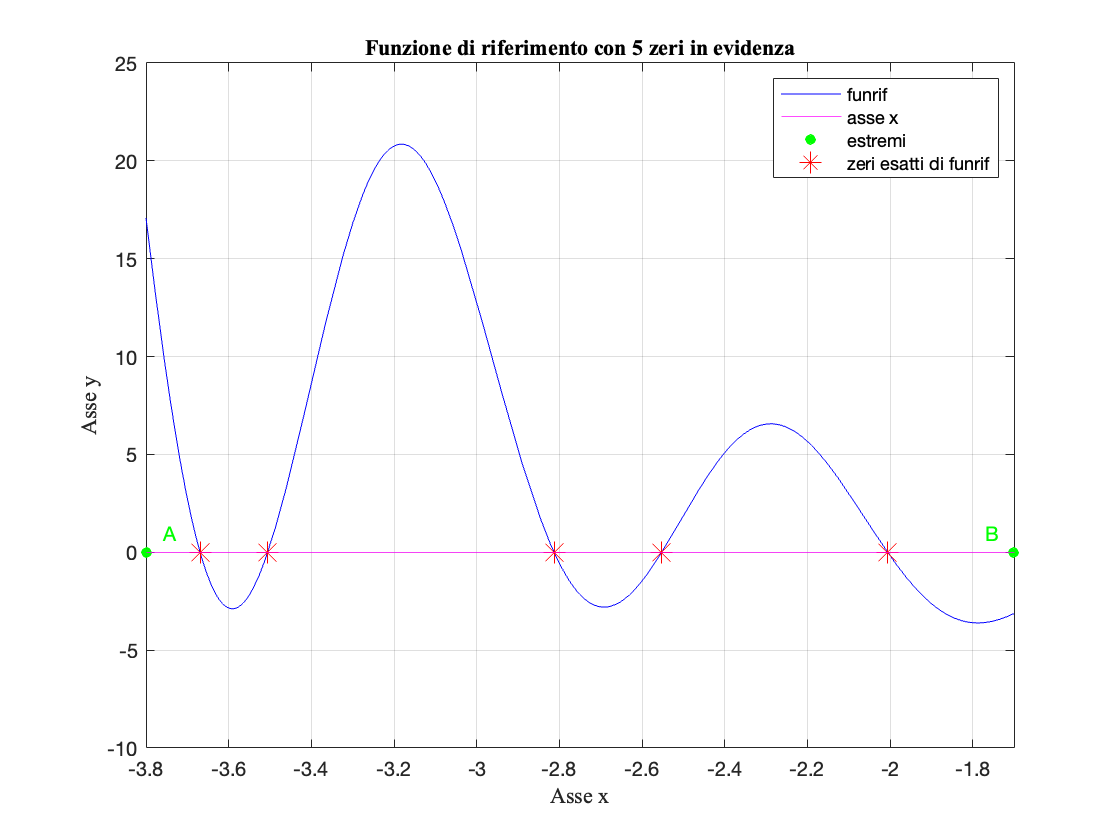

plot([z1 z2 z3 z4 z5],[0 0 0 0 0],'*','markersize',10,'color','r') %utilizzo il simbolo * per evidenziare i miei 5 zeri (esatti) dopo averli trovati con fzero.
legend('funrif','asse x','estremi','zeri esatti di funrif') %creo la leggenda per il grafico

**PUNTO 4: determinate un'approssimazione dei 5 zeri, usando il metodo di bisezione (nostra function **`bisezione`**) per lo zero più piccolo, il metodo delle Secanti (nostra function **`Secanti`**) per il secondo e terzo zero  e il metodo di Newton (nostra function **`Newton`**) per il quarto e il quinto zero (consiglio: usare **`funtool`** per determinare l'espressione della derivata della funzione di riferimento), con un valore di **`delta_ass`** che garantisca, in tutti e 5 i casi, che la parte intera e le prime 6 cifre frazionarie siano corrette;**

*Calcolo un'approssimazione per lo zero più piccolo usando il Metodo di Bisezione:*

delta_ass=1e-6; %creo variabile delta_ass per fissare la stima del massimo errore assoluto richiesto sul risultato 
zerobis=bisezione(funrif,-3.6695,-3.6668,delta_ass)

zerobis =   -3.669235998535156


%NOTE SULLA FUNCTION bisezione:
% la funzione ha come primo argomento l'handle alla function che implementa la funzione funrif.
% la funzione ha come secondo e terzo argomento gli estremi dell'intervallo iniziale (per lo zero più piccolo) 
% la funzione ha come ultimo argomento l'accuratezza che si vuole sul risultato da calcolare

*Calcolo un'approssimazione per il secondo e per il terzo zero usando il Metodo delle Secanti:*

kmax=10; %fisso il numero massimo di iterazioni consentite e lo assegno alla variabile kmax

Per il primo zero:

zerosec1=Secanti(funrif,-3.50524,-3.50523,delta_ass,kmax) %uso la function Secanti per il secondo zero

zerosec1 =   -3.505500384446340


Per il secondo zero:

zerosec2=Secanti(funrif,-2.8125,-2.8124,delta_ass,kmax) %uso la function Secanti per il terzo zero

zerosec2 =   -2.812693477343854


%NOTE SULLA FUNCTION Secanti:
% Il primo argomento della funzione è l'handle alla function funrif
% Il secondo ed il terzo argomento della funzione sono la prima e la seconda approssimazione iniziale della soluzione (per il secondo ed il terzo zero)
% Delta_ass e kmax sono, rispettivamente, il massimo errore assoluto
% richiesta sul risultato ed il contatore del massimo numero di iterazioni consentite (10 nel nostro caso)

*Metodo di Newton: *

%Mi calcolo la DERIVATA PRIMA della mia funzione di riferimento funrif
derivata = @(x) - cos((7.*x)./2 - pi./2).^2.*exp(-x) - (10.*sin(2.*x))./(2.*x.^2 + 1) - (20.*x.*cos(2.*x))./(2.*x.^2 + 1).^2 - 7.*cos((7.*x)./2 - pi./2).*sin((7.*x)./2 - pi./2).*exp(-x)   

derivata = function_handle with value:
    @(x)-cos((7.*x)./2-pi./2).^2.*exp(-x)-(10.*sin(2.*x))./(2.*x.^2+1)-(20.*x.*cos(2.*x))./(2.*x.^2+1).^2-7.*cos((7.*x)./2-pi./2).*sin((7.*x)./2-pi./2).*exp(-x)


zeronew1= Newton(funrif,derivata,-2.55,delta_ass,kmax) %uso la function Newton per il quarto zero

zeronew1 =   -2.552236378948009


zeronew2= Newton(funrif,derivata,-2.00,delta_ass,kmax) %uso la function Newton per il quinto zero

zeronew2 =   -2.005756010404108


%NOTE SULLA FUNCTION Newton:
% Il primo argomento è un puntatore alla function che definisce la funzione di cui si vuole calcolare lo zero
% derivata è una function che definisce f', xiniz è la prima approssimazione della successione delle approssimazioni
% delta_ass è il massimo errore consentito sull'approssimazione e siccome il metodo non converge sempre, kmax è il numero massimo di iterazioni consentite (dichiarato precedentemente e inizializzato a 10).

Tornando al punto 3 è possibile verificare che i valori (esatti) degli zeri combaciano, almeno per le prime sei cifre dopo la virgola, con gli zeri appena calcolati con i metodi bisezione, Secanti e Newton.

Mostro ora i due zeri di Newton assieme alla derivata passante tra essi:

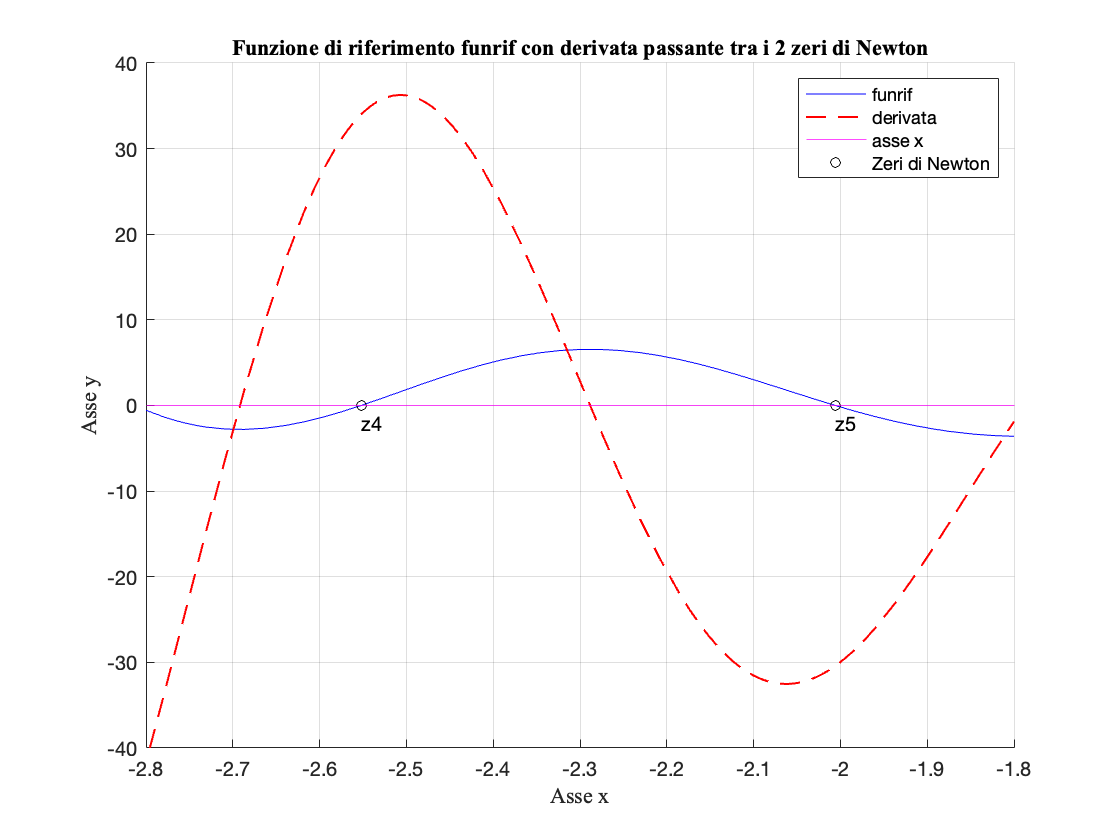

figure(4) %Creo quarta figura
hold on %hold on mi permette di conservare i grafici negli assi correnti (i nuovi grafici non eliminano quelli già esistenti)
fplot(funrif,[a,b],'color','b') %definisco intervalli per la funzione di riferimento funrif
fplot(derivata,[a,b],"--", "LineWidth",1, 'color','r') %definisco intervalli per la derivata prima della funzione di riferimento funrif
axis([-2.8 -1.8 -40 40]) %scelgo gli intervalli per visualizzare un'area specifica (zeri di Newton)
hold on %hold on mi permette di conservare i grafici negli assi correnti (i nuovi grafici non eliminano quelli già esistenti)
grid on %grid on ci fa visualizzare la griglia

xlabel("Asse x",'FontName','Times New Roman') %do un nome all'asse x
ylabel("Asse y",'FontName','Times New Roman') %do un nome all'asse y
title("Funzione di riferimento funrif con derivata passante tra i 2 zeri di Newton",'FontName','Times New Roman') %do un titolo al grafico
text(zeronew1,-2,'z4')
text(zeronew2,-2,'z5')
yline(0,'-','color','m') %evidenzio l'asse delle x

plot([zeronew1 zeronew2],[0 0],'o','markersize',5,'color','k') %segno gli zeri con il simbolo o
legend('funrif','derivata','asse x','Zeri di Newton') %Creo la leggenda
hold off %Un nuovo tracciato non sarà unito a quello attuale

**PUNTO 5: considerate sia l'errore assoluto tra l'approssimazione della bisezione e la corrispondente soluzione esatta, sia l'errore assoluto tra l'approssimazione delle Secanti e la corrispondente soluzione esatta (per entrambi gli zeri calcolati con le Secanti), sia l'errore assoluto tra l'approssimazione di Newton e la corrispondente soluzione esatta (per entrambi gli zeri calcolati con Newton) e verificate che siano minori dell'accuratezza richiesta (**`delta_ass`**), commentando il loro valore; calcolate anche il residuo per ognuna delle cinque approssimazioni e commentate i valori del residuo confrontandoli con quelli del corrispondente errore assoluto  e con l'accuratezza richiesta; guardando il grafico della funzione di riferimento dire se, per ognuno dei cinque zeri, il problema appare bene o mal condizionato e poi calcolare l'indice di condizionamento per ognuno dei cinque zeri;**

%Calcolo l'errore assouluto mettendo a confronto il primo zero con lo zero di bisezione
erass_metbi= abs(zerobis-z1) %Alla funzione abs, che permette di ottenere il valore assoluto di ogni numero o vettore, passo come argomento lo zero di bisezione a cui sottraggo il valore di z1 (ovvero del primo zero)

erass_metbi =      2.171723032518003e-07


%effettuo il controllo logico, ovvero verifico se l'errore assoluto del metodo bisezione è minore o uguale di delta_ass
if erass_metbi<=delta_ass
    fprintf("erass_metbi è minore o uguale di delta_ass poichè il risultato di erass_metbi è %g", erass_metbi)
else
    fprintf("erass_metbi è maggiore di delta_ass poichè il risultato di erass_metbi è %g", erass_metbi) 
end    

erass_metbi è minore o uguale di delta_ass poichè il risultato di erass_metbi è 2.17172e-07

%Alla funzione abs, che permette di ottenere il valore assoluto di ogni numero o vettore, passo come argomento lo zero di secante (1) a cui sottraggo il valore di z2  (ovvero del secondo zero)
erass_metsec1= abs(zerosec1-z2)   

erass_metsec1 =      3.070315166553428e-07



%Effettuo il controllo logico, ovvero verifico se l'errore assoluto del metodo secante (1) è minore o uguale di delta_ass
if erass_metsec1<=delta_ass 
     fprintf("erass_metsec1 è minore o uguale di delta_ass poichè il risultato di erass_metsec1 è %g", erass_metsec1)
else 
    fprintf("erass_metsec1 è maggiore di delta_ass poichè il risultato di erass_metsec1 è %g", erass_metsec1) 
end

erass_metsec1 è minore o uguale di delta_ass poichè il risultato di erass_metsec1 è 3.07032e-07

%Alla funzione abs, che permette di ottenere il valore assoluto di ogni numero o vettore, passo come argomento lo zero di secante (2) a cui sottraggo il valore di z3 (ovvero del terzo zero)
erass_metsec2= abs(zerosec2-z3) 

erass_metsec2 =      2.211258429696272e-07



%Effettuo il controllo logico, ovvero verifico se l'errore assoluto del metodo secante (2) è minore o uguale di delta_ass
if erass_metsec2<=delta_ass 
     fprintf("erass_metsec2 è minore o uguale di delta_ass poichè il risultato di erass_metsec2 è %g", erass_metsec2)
else 
    fprintf("erass_metsec2 è maggiore di delta_ass poichè il risultato di erass_metsec2 è %g", erass_metsec2) 
end

erass_metsec2 è minore o uguale di delta_ass poichè il risultato di erass_metsec2 è 2.21126e-07

%Calcolo l'errore assoluto confrontando il quarto zero con lo zero di newton (1)
erass_metnew1= abs(zeronew1-z4) %Alla funzione abs, che permette di ottenere il valore assoluto di ogni numero o vettore, passo come argomento lo zero di Newton (1) a cui sottraggo il valore di z4 (ovvero del quarto zero)

erass_metnew1 =      7.527489742642501e-11



%Effettuo il controllo logico, ovvero verifico se l'errore assoluto del metodo newton (1) è minore o uguale di delta_ass
if erass_metnew1<=delta_ass 
    fprintf("erass_metnew1 è minore o uguale di delta_ass poichè il risultato di erass_metnew1 è %g",erass_metnew1)
else
    fprintf("erass_metnew1 è maggiore di delta_ass poichè il risultato di erass_metnew1 è %g",erass_metnew1)
end

erass_metnew1 è minore o uguale di delta_ass poichè il risultato di erass_metnew1 è 7.52749e-11

%Calcolo l'errore assoluto confrontando il quinto zero con lo zero di newton (2) 
erass_metnew2= abs(zeronew2-z5) %Alla funzione abs, che permette di ottenere il valore assoluto di ogni numero o vettore, passo come argomento lo zero di Newton (2) a cui sottraggo il valore di z5 (ovvero del quinto zero)

erass_metnew2 =      2.128462739392489e-09


%Effettuo il controllo logico, ovvero verifico se l'errore assoluto del metodo newton (2) è minore o uguale di delta_ass
if erass_metnew2<=delta_ass 
     fprintf("erass_metnew2 è minore o uguale di delta_ass poichè il risultato di erass_metnew2 è %g",erass_metnew2)
else
    fprintf("erass_metnew2 è maggiore di delta_ass poichè il risultato di erass_metnew2 è %g",erass_metnew2)
end

erass_metnew2 è minore o uguale di delta_ass poichè il risultato di erass_metnew2 è 2.12846e-09

Calcolo i residui:

%Calcolo i residui di bisezione
residuo_zerobis= abs(funrif(zerobis)) %Alla funzione abs, che permette di ottenere il valore assoluto di ogni numero o vettore, passo come argomento funrif(zerobis)

residuo_zerobis =      1.618585349616453e-05


L'ordine di grandezza del residuo dell'approssimazione del metodo di bisezione è simile all'accuratezza richiesta 10^-6. Ciò indica che il problema è ben condizionato.

%Calcolo i residui di secante (1)
residuo_zerosec1= abs(funrif(zerosec1)) %Alla funzione abs, che permette di ottenere il valore assoluto di ogni numero o vettore, passo come argomento funrif(zerosec1)

residuo_zerosec1 =      1.926193612300509e-05


L'ordine di grandezza del residuo dell'approssimazione del metodo Secante (1) è simile all'accuratezza richiesta 10^-6. Ciò indica che il problema è ben condizionato.

%Calcolo i residui di secante (2)
residuo_zerosec2= abs(funrif(zerosec2)) %Alla funzione abs, che permette di ottenere il valore assoluto di ogni numero o vettore, passo come argomento funrif(zerosec2)

residuo_zerosec2 =      1.024917330072483e-05


L'ordine di grandezza del residuo dell'approssimazione del metodo Secante (2) è simile all'accuratezza richiesta 10^-6. Ciò indica che il problema è ben condizionato.

%Calcolo i residui di Newton (1)
residuo_zeronew1= abs(funrif(zeronew1)) %Alla funzione abs, che permette di ottenere il valore assoluto di ogni numero o vettore, passo come argomento funrif(zeronew1)

residuo_zeronew1 =      2.558158129772892e-09


L'ordine di grandezza del residuo dell'approssimazione del metodo Newton(1) è simile all'accuratezza richiesta 10^-6. Ciò indica che il problema è ben condizionato.

%Calcolo i residui di Newton (2)
residuo_zeronew2= abs(funrif(zeronew2)) %Alla funzione abs, che permette di ottenere il valore assoluto di ogni numero o vettore, passo come argomento funrif(zeronew2)

residuo_zeronew2 =      6.471904656635274e-08


L'ordine di grandezza del residuo dell'approssimazione del metodo Newton(2) è simile all'accuratezza richiesta 10^-6. Ciò indica che il problema è ben condizionato.

Calcolo indici di condizionamento:

%Metodo bisezione
i_cond_bis= 1/abs(derivata(z1)) %risultato dato dal rapporto tra 1 e la function abs a cui passo derivata(z1)

i_cond_bis =    0.013417433212398


%Metodo Secanti
i_cond_sec1= 1/abs(derivata(z2))  %risultato dato dal rapporto tra 1 e la function abs a cui passo derivata(z2)

i_cond_sec1 =    0.015939826941938


i_cond_sec2= 1/abs(derivata(z3)) %risultato dato dal rapporto tra 1 e la function abs a cui passo derivata(z3)

i_cond_sec2 =    0.021575011674604


%Metodo Newton
i_cond_new1= 1/abs(derivata(z4)) %risultato dato dal rapporto tra 1 e la function abs a cui passo derivata(z4)

i_cond_new1 =    0.029425467380536


i_cond_new2= 1/abs(derivata(z5)) %risultato dato dal rapporto tra 1 e la function abs a cui passo derivata(z5)

i_cond_new2 =    0.032887734802568


Visualizzo graficamente la funzione in uno specifico intervallo [a,b] mettendo in evidenza la derivata passante per i due punti di minimo e i due punti di massimo.

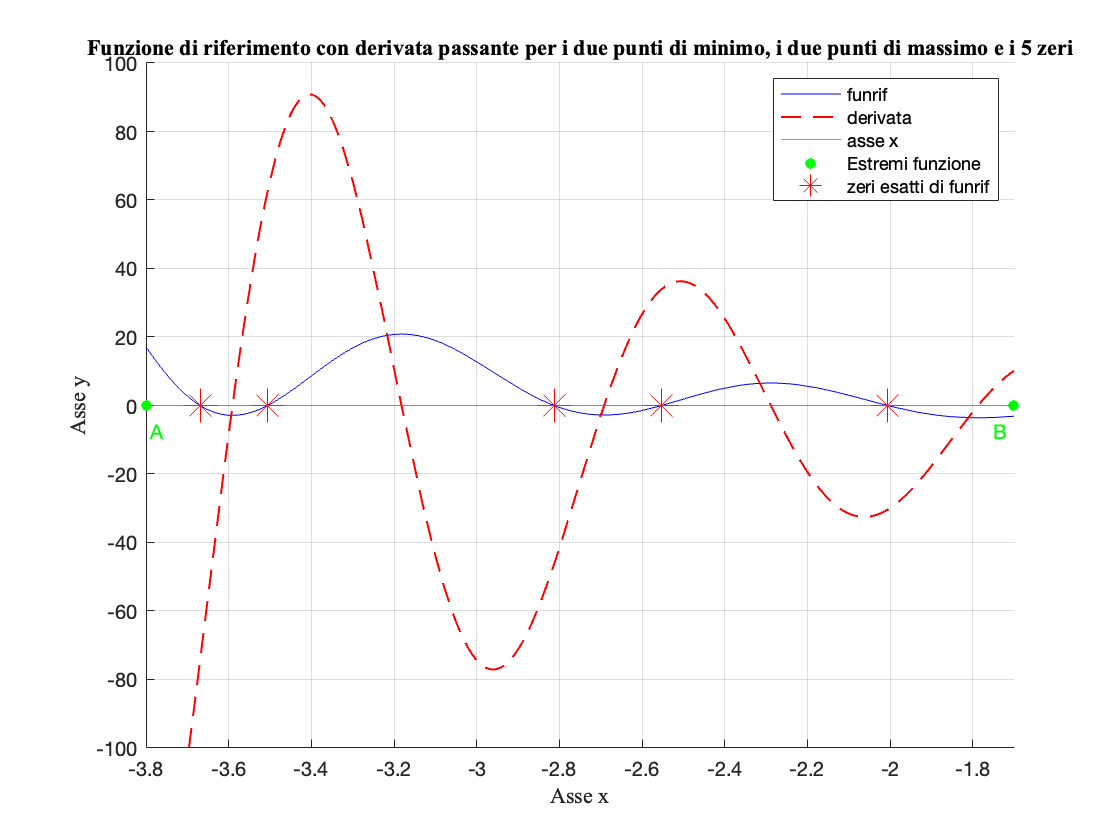

figure(5) %Creo quinta figura
hold on %hold on mi permette di conservare i grafici negli assi correnti (i nuovi grafici non eliminano quelli già esistenti)
fplot(funrif,[a,b],'color','b') %definisco intervalli per la funzione di riferimento funrif
fplot(derivata,[a,b],"--", "LineWidth",1, 'color','r') %definisco intervalli per la derivata prima della funzione di riferimento funrif
axis([a b -100 100]) %scelgo gli intervalli per visualizzare un'area specifica
hold on %hold on mi permette di conservare i grafici negli assi correnti (i nuovi grafici non eliminano quelli già esistenti)
grid on %grid on ci fa visualizzare la griglia

xlabel("Asse x",'FontName','Times New Roman') %do un nome all'asse x
ylabel("Asse y",'FontName','Times New Roman') %do un nome all'asse y
title("Funzione di riferimento con derivata passante per i due punti di minimo, i due punti di massimo e i 5 zeri",'FontName','Times New Roman') %do un titolo al grafico


yline(0,'-','color','m') %evidenzio l'asse delle x
%evidenzio gli estremi
text(-3.79,-7.5,'A', "Color", 'g', "FontSize",10.0); %aggiunge lettera A all'estremo sinistro
text(-1.75,-7.5,'B', 'color','g', "FontSize",10.0); %aggiunge lettera B all'estremo destro

plot([a,b],[0,0],'o','markersize',5,'color','g','MarkerFaceColor','g') %aggiungo pallino verde per segnare gli estremi
plot([z1 z2 z3 z4 z5],[0 0 0 0 0],'*','markersize',15,'color','r') %segno gli zeri con il simbolo *
legend('funrif','derivata','asse x','Estremi funzione','zeri esatti di funrif') %Creo la leggenda
hold off %Un nuovo tracciato non sarà unito a quello attuale

**PUNTO 6: osservando il grafico della vostra funzione di riferimento nell'intervallo **$[a,b]$**e della bisettrice, stabilite se ci sono punti fissi e determinate il loro numero; poi, senza usare la function **`PFisso (suggerimento: `**usate opportunamente**` fzero)`**, calcolate una approssimazione del punto fisso più vicino all'estremo sinistro dell'intervallo, cioè più vicino ad **$a$**, e determinate il residuo; dite se il metodo del punto fisso convergerebbe a tale punto fisso.**

Visualizzo la funzione graficamente mostrando la bisettrice:

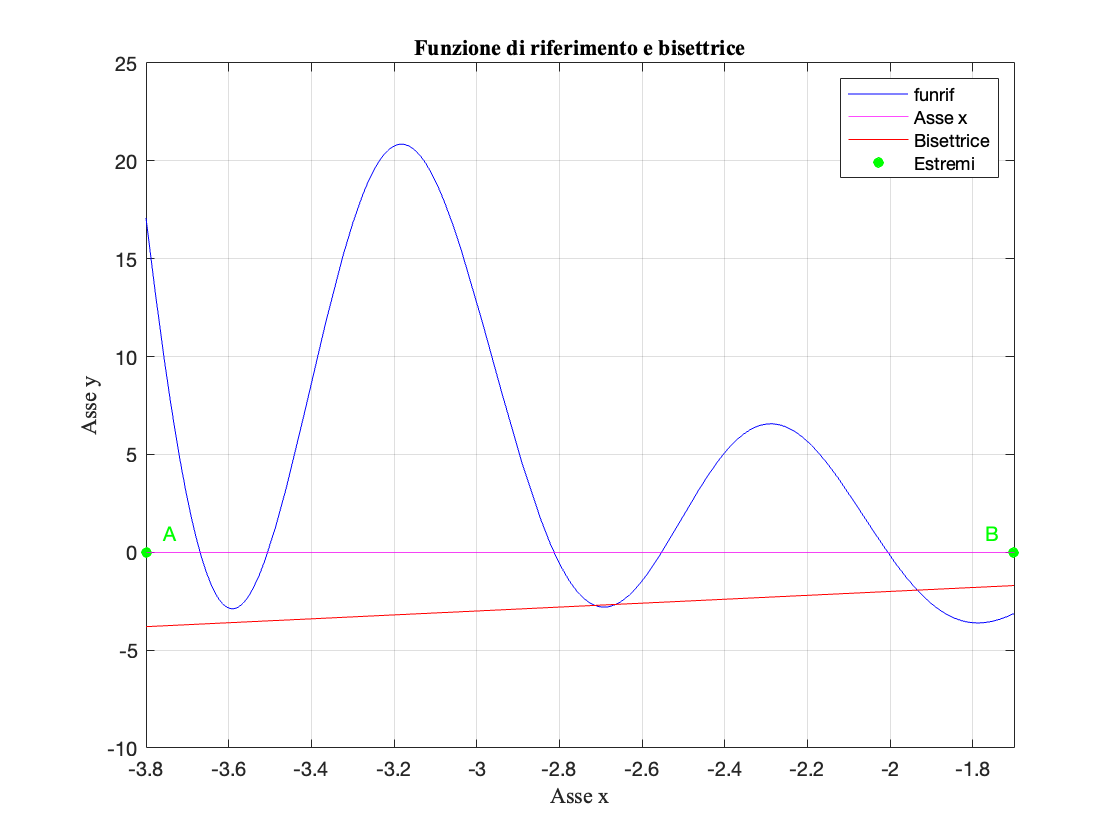

figure (6) %creo la sesta figura
fplot(funrif,[a,b],'color','b') %definisco intervallo funzione di riferimento funrif
axis([a b -10 25]) %tramite il comando axis definisco le coordinate per poter visualizzare un'area precisa del grafico
hold on %hold on mi permette di conservare i grafici negli assi correnti (i nuovi grafici non eliminano quelli già esistenti)
grid on %grid on ci fa visualizzare la griglia
yline(0,'-','color','m') %evidenzio asse delle x
xlabel("Asse x",'FontName','Times New Roman') %do un nome all'asse x
ylabel("Asse y",'FontName','Times New Roman') %do un nome all'asse y
title("Funzione di riferimento e bisettrice",'FontName','Times New Roman') %do un titolo al grafico
biset=linspace(a,b,5); %uso la function per creare la bisettrice passando gli estremi A e B e 5 punti
%La funzione linspace di matlab genera dei vettori riga linearmente intervallati.
% La sintassi è linspace(min,max,num) dove  Min-max sono gli estremi dell'intervallo in cui generare i numeri e num è il numero di elementi da generare nell'intervallo specificato.
plot(biset,biset,'color','r') %passo due volte l'argomento biset alla function plot per visualizzare la bisettrice sul grafico
text(-3.76,1,'A', "Color", 'g',"FontSize",10.0); %aggiungo lettera A all'estremo sinistro
text(-1.77,1,'B', 'color','g',"FontSize",10.0); %aggiungo lettera B all'estremo destro
 
plot([a,b],[0,0],'o','markersize',5,'color','g','MarkerFaceColor','g') %aggiungo pallini verdi agli estremi
legend({'funrif','Asse x','Bisettrice','Estremi'}) %Creo la leggenda
hold off %Un nuovo tracciato non sarà unito a quello attuale

                                                      CI SONO TRE PUNTI FISSI.

Faccio uno zoom sui primi due punti fissi per visualizzarli meglio:

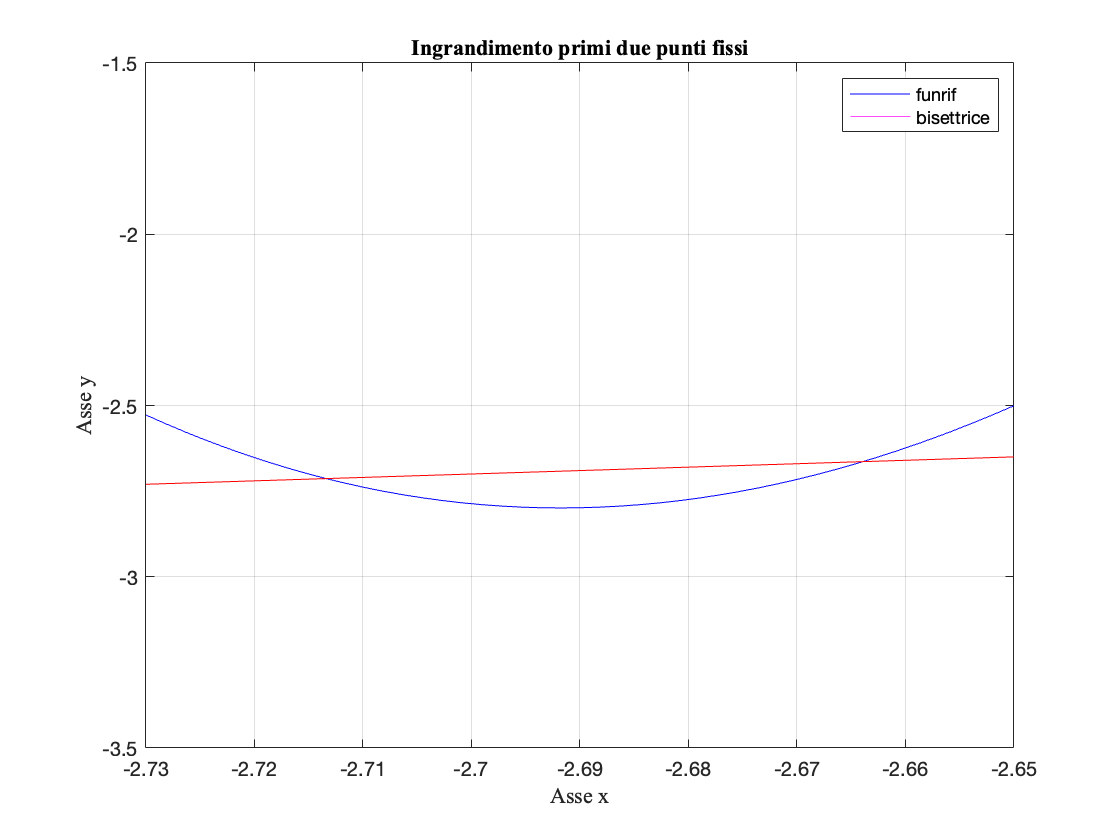

figure (7) %creo settima figura
fplot(funrif,[a,b],'color','b') %definisco intervalli della funzione di riferimento funrif
axis([-2.73 -2.65 -3.5 -1.5]) %definisco intervallo per visualizzare una specifica area (per visualizzare i primi due punti fissi poco visibili nella figura precedente) 
hold on %hold on mi permette di conservare i grafici negli assi correnti (i nuovi grafici non eliminano quelli già esistenti)
grid on %grid on ci fa visualizzare la griglia
yline(0,'-','color','m') %evidenzio asse x
xlabel("Asse x",'FontName','Times New Roman') %do un nome all'asse delle x
ylabel("Asse y",'FontName','Times New Roman') %do un nome all'asse delle y
title("Ingrandimento primi due punti fissi",'FontName','Times New Roman') %do un nome al grafico
%La funzione linspace di matlab genera dei vettori riga linearmente intervallati.
% La sintassi è linspace(min,max,num) dove  Min-max sono gli estremi delldintervallo in cui generare i numeri e num è il numero di elementi da generare nell'intervallo specificato.
biset=linspace(a,b,5); %uso la function per creare la bisettrice passando gli estremi a ed b e 5 punti
plot(biset,biset,'color','r') %passo due volte l'argomento biset alla function plot per visualizzare la bisettrice sul grafico
legend({'funrif','bisettrice'}) %Creo leggenda

Calcolo ora il punto fisso più vicino all'estremo sinistro dell'intervallo [a,b] :

puntofisso=fzero(@(x)funrif(x)-x,-2.75)

puntofisso =   -2.713396960765414


%Calcolo il residuo
residuo_puntofisso=abs(funrif(puntofisso)-puntofisso)

residuo_puntofisso =      0


Visualizzo il punto fisso più vicino all'estremo sinistro:

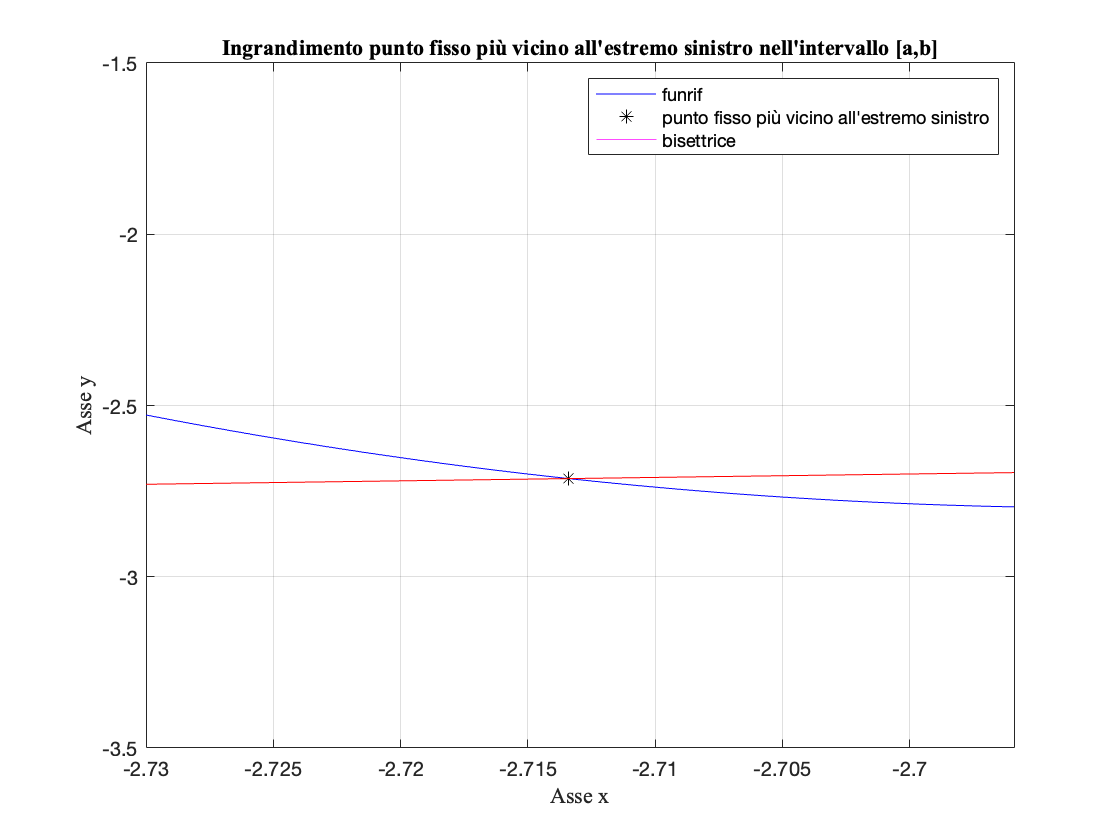

figure (8) %creo ottava figura
fplot(funrif,[a,b],'color','b') %definisco intervallo per la funzione di riferimento funrif
axis([-2.73 -2.6959 -3.5 -1.5]) %definisco intervalli per una specifica area da visualizzare 
hold on %hold on mi permette di conservare i grafici negli assi correnti (i nuovi grafici non eliminano quelli già esistenti)
plot(puntofisso,puntofisso,'*','color','k') %metto il simbolo * sul primo punto fisso 
grid on %grid on ci fa visualizzare la griglia
yline(0,'-','color','m') %Evidenzio asse delle x
xlabel("Asse x",'FontName','Times New Roman') %do nome all'asse x
ylabel("Asse y",'FontName','Times New Roman') %do nonme all'asse y
title("Ingrandimento punto fisso più vicino all'estremo sinistro nell'intervallo [a,b]",'FontName','Times New Roman') %do titolo al grafico
biset=linspace(a,b,5); %uso la function per creare la bisettrice passando gli estremi a ed b e 5 punti
plot(biset,biset,'color','r') %passo due volte l'argomento biset alla function plot per visualizzare la bisettrice sul grafico
legend({'funrif','punto fisso più vicino all''estremo sinistro','bisettrice'}) % Creo la leggenda 

c=abs(derivata(puntofisso)) %il metodo del punto fisso ha una convergenza generalmente lineare con costante di proporzionalità c data dal valore assoluto della derivata prima di 'derivata' nel punto fisso

c =    8.000859264416631


Il valore assoluto della derivata prima, calcolata in puntofisso (approssimativamente), è 8.000859264416631 (quindi maggiore di 0). Sapendo che se c>1 il metodo diverge, allora in questo caso, poichè c è maggiore di 1, il metodo diverge.

**PUNTO 7: usate la function Matlab **`fminbnd`** per determinare i due punti di minimo e i due punti di massimo della vostra funzione di riferimento in **$[a,b]$**, con quattro chiamate del tipo: **`fminbnd(fun,sinistro,destro,optimset('TolX',1e-10))`**, e considerate i valori calcolati da **`fminbnd`** come le soluzioni esatte (cioè come valori esatti dei due punti di minimo e dei due punti di massimo);**

Determino i due punti di minimo e i due punti di massimo della funzione di riferimento funrif tramite la chiamata a fminbnd

MIN1=fminbnd(funrif,-3.7,-3.5,optimset('TolX',1e-10)) %primo punto di minimo  (soluzione esatta)

MIN1 =   -3.590790412214743


MIN2=fminbnd(funrif,-2.8,-2.6,optimset('TolX',1e-10)) %secondo punto di minimo (soluzione esatta)

MIN2 =   -2.691780955333804


Ho bisogno di calcolare l'inversa della funzione di riferimento funrif (ciò mi serve per trovare i punti di massimo):

inversa_funrif=@(x) -funrif(x); %calcolo l'inversa della funzione di riferimento e la assegno alla variabile inversa_funrif

MAX1=fminbnd(inversa_funrif,-3.25,-3.1,optimset('TolX',1e-10)) %primo punto di massimo (soluzione esatta)

MAX1 =   -3.181832577860471


MAX2=fminbnd(inversa_funrif,-2.4,-2.15,optimset('TolX',1e-10)) %secondo punto di massimo (soluzione esatta)

MAX2 =   -2.288314785993240


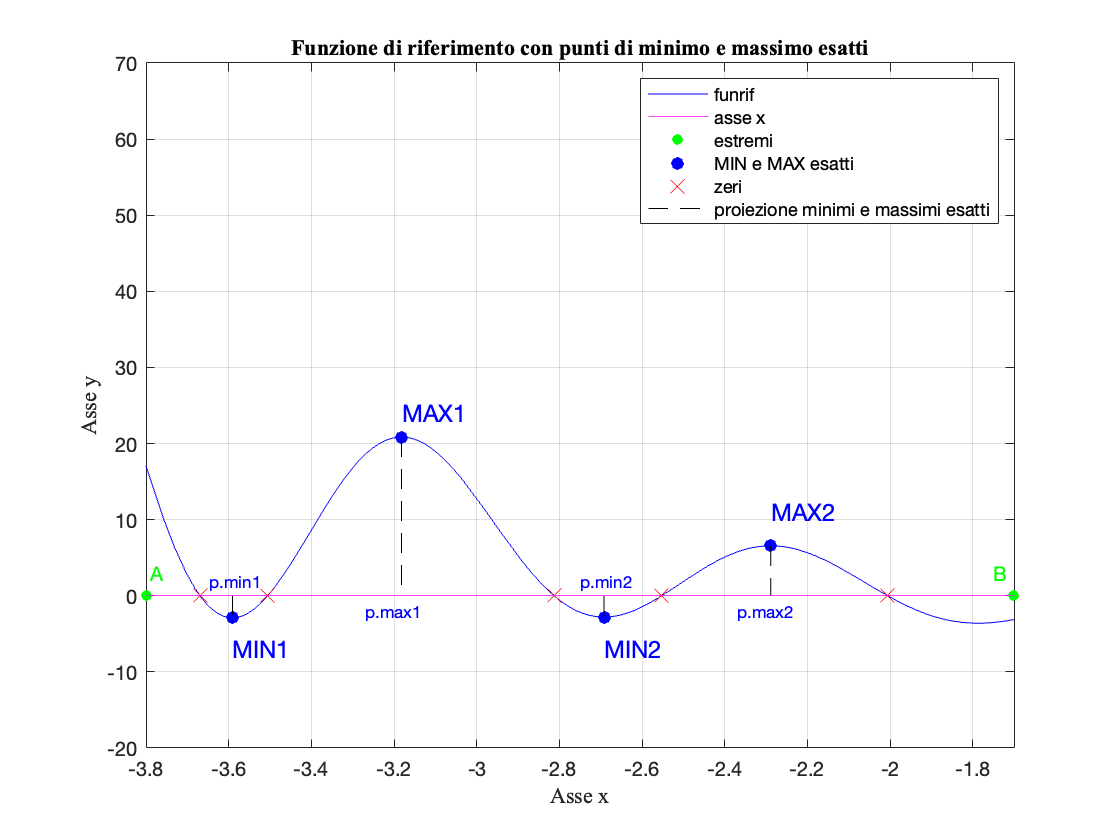

figure(9) %creo nona figura
fplot(funrif,[a,b],'color','b') %scelgo l'intervallo [a,b] della mia funzione di riferimento
axis([a b -20 70]) %definisco intervalli per una specifica area da visualizzare 
hold on %hold on mi permette di conservare i grafici negli assi correnti (i nuovi grafici non eliminano quelli già esistenti)
grid on %grid on ci fa visualizzare la griglia

xlabel("Asse x",'FontName','Times New Roman') %do nome all'asse x
ylabel("Asse y",'FontName','Times New Roman') %do nome all'asse y
title("Funzione di riferimento con punti di minimo e massimo esatti",'FontName','Times New Roman')

yline(0,'-','color','m') %evidenzio asse x
%evidenzio gli estremi
text(-3.79,3,'A', "Color", 'g', "FontSize",10.0); %aggiunge lettera A all'estremo sinistro
text(-1.75,3,'B', 'color','g', "FontSize",10.0); %aggiunge lettera B all'estremo destro

plot([a,b],[0,0],'o','markersize',5,'color','g','MarkerFaceColor','g') %aggiungo pallino verde per segnare gli estremi

text(MIN1,-7, "MIN1","Color",'b',"FontSize",12) %indico (in maniera precisa) il primo minimo
text(MIN2,-7, "MIN2","Color",'b',"FontSize",12) %indico (in maniera precisa) il secondo minimo
text(MAX1,24,"MAX1","Color",'b',"FontSize",12) %indico (in maniera precisa) il primo massimo
text(MAX2,11.0,"MAX2","Color",'b',"FontSize",12) %indico (in maniera precisa) il secondo massimo
plot([MIN1 MAX1 MIN2 MAX2], [funrif(MIN1) funrif(MAX1) funrif(MIN2) funrif(MAX2)], 'o','color','b','MarkerFaceColor','b') %minimi e massimi esatti
% Segno le coordinate degli zeri con una x per poterli visualizzare facilmente
plot([z1 z2 z3 z4 z5],[0 0 0 0 0],'x','markersize',9,'color','r')
%proietti sia i 2 minimi che i 2 massimi
plot([MIN1,MIN1], [0,funrif(MIN1)], '--','color','k')
plot([MAX1,MAX1], [funrif(MAX1),0], '--','color','k')
plot([MIN2,MIN2], [0,funrif(MIN2)], '--','color','k')
plot([MAX2,MAX2], [funrif(MAX2),0], '--','color','k')

text(-3.647,2,'p.min1', "Color", 'b',"FontSize",8.5); %aggiungo una scritta per visualizzare facilmente il primo minimo
text(-3.27,-2,'p.max1', "Color", 'b',"FontSize",8.5); %aggiungo una scritta per visualizzare facilmente il primo massimo
text(-2.75,2,'p.min2', "Color", 'b',"FontSize",8.5); %aggiungo una scritta per visualizzare facilmente il secondo minimo
text(-2.37,-2,'p.max2', "Color", 'b',"FontSize",8.5); %aggiungo una scritta per visualizzare facilmente il secondo massimo


legend('funrif','asse x','estremi','MIN e MAX esatti','zeri','proiezione minimi e massimi esatti')

**PUNTO 8: verificate che i due punti di minimo e i due punti di massimo sono zeri della derivata della vostra funzione di riferimento (consiglio: usare **`funtool`** per determinare l'espressione della derivata della funzione di riferimento), visualizzando nella stessa figura sia il grafico della funzione sia il grafico della sua derivata (può essere utile usare anche la scalatura della finestra grafica data dal comando **`axis([xmin xmax ymin ymax])`** ), e usando la **`fzero`** per calcolare tutti gli zeri della derivata; commentate i risultati ottenuti;**

zeroderivata1=fzero(derivata,-3.590) %Calcolo il primo zero della derivata corrispondente al primo minimo

zeroderivata1 =   -3.590790412982147


zeroderivata2=fzero(derivata,-3.181) %Calcolo il secondo zero della derivata corrispondente al primo massimo

zeroderivata2 =   -3.181832576887745


zeroderivata3=fzero(derivata,-2.691) %Calcolo il terzo zero della derivata corrispondente al secondo minimo

zeroderivata3 =   -2.691780956280296


zeroderivata4=fzero(derivata,-2.288) %Calcolo il quarto zero della derivata corrispondente al  secondo massimo

zeroderivata4 =   -2.288314781621120


I risultati degli zeri della derivata differiscono per le ultime cifre frazionarie rispetto ai risultati dei minimi e dei massimi della funrif, ciò dipende dall'accuratezza della funzione. Nonostante ciò possiamo concludere che i risultati siano ugualemente coincidenti come ci aspettavamo.

Visualizziamo il grafico:

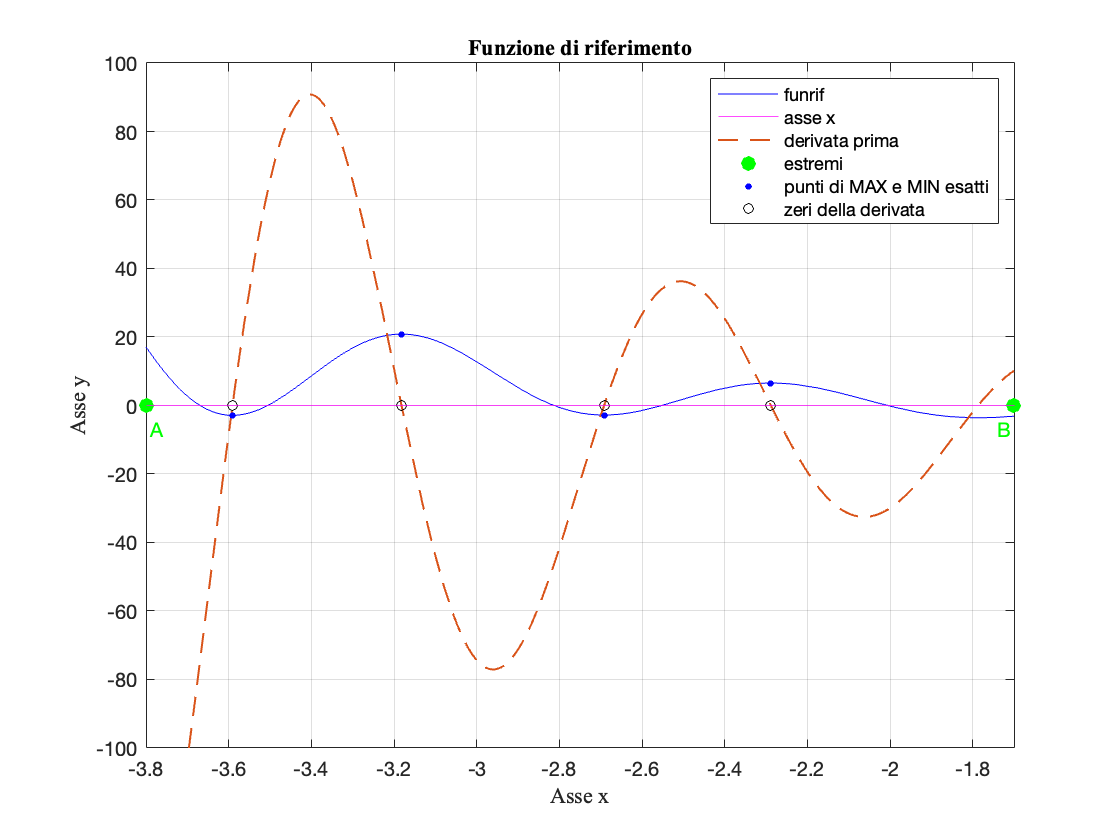

figure(10) %Creo la decima figura
fplot(funrif,[a,b],'color','b') %scelgo l'intervallo [a,b] della mia funzione di riferimento
axis([a b -100 100]) %definisco intervalli per una specifica area da visualizzare
hold on %hold on mi permette di conservare i grafici negli assi correnti (i nuovi grafici non eliminano quelli già esistenti)
grid on %grid on ci fa visualizzare la griglia

xlabel("Asse x",'FontName','Times New Roman') %do un nome all'asse x
ylabel("Asse y",'FontName','Times New Roman') %do un nome all'asse y
title("Funzione di riferimento",'FontName','Times New Roman') %do un titolo al grafico

yline(0,'-','color','m') %evidenzio l'asse delle x

fplot(derivata,[a,b],"--","LineWidth",1) %visualizzo intervallo della derivata prima
%evidenzio gli estremi
text(-3.79,-7,'A', "Color", 'g', "FontSize",10.0); %aggiunge lettera A all'estremo sinistro
text(-1.74,-7,'B', 'color','g', "FontSize",10.0); %aggiunge lettera B all'estremo destro
plot([a,b],[0,0],'o','markersize',7,'color','g','MarkerFaceColor','g') %segno estremi con un cerchietto

plot([MIN1 MAX1 MIN2 MAX2], [funrif(MIN1) funrif(MAX1) funrif(MIN2) funrif(MAX2)], 'o','color','b','markersize',3,'MarkerFaceColor','b') %minimi e massimi esatti

plot([zeroderivata1 zeroderivata2 zeroderivata3 zeroderivata4],[0 0 0 0],'o','markersize',5,'color','k') %visualizzo cerchietti per evidenziare zeri della derivata
legend('funrif','asse x','derivata prima','estremi','punti di MAX e MIN esatti','zeri della derivata') %creo leggenda

**PUNTO 9: determinate un'approssimazione dei due punti di minimo e dei due punti di massimo, usando, rispettivamente, due volte il metodo di Fibonacci search (nostra function **`fminfibo`**) per i due minimi, e il metodo di Golden search (nostra function **`fmingolden`**) per i due massimi, con un valore di **`delta_ass`** che garantisca che la parte intera e le prime 3 cifre frazionarie siano corrette; **

Creo la nuova variabile delta_ass:

new_delta_ass=1e-3;

minfibo1 = fminfibo(funrif,-3.8,-3.4,new_delta_ass) %primo punto di minimo (Fibonacci Search)

minfibo1 =   -3.590557939914163


maxgolden1 = fmingolden(inversa_funrif,-3.4,-3.0,new_delta_ass) %primo punto di massimo (Golden Search)

maxgolden1 =   -3.181966011250104


minfibo2 = fminfibo(funrif,-2.8,-2.6,new_delta_ass) %secondo punto di minimo (Fibonacci Search) 

minfibo2 =   -2.691666666666666


maxgolden2 = fmingolden(inversa_funrif,-2.4,-2.2,new_delta_ass) %secondo punto di massimo (Golden Search)

maxgolden2 =   -2.288233257996803


**PUNTO 10: considerate l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Golden search e le due corrispondenti soluzioni esatte e poi l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Fibonacci search e le due corrispondenti soluzioni esatte, e verificate che siano in tutti e quattro i casi minori dell'accuratezza richiesta (**`delta_ass`**), commentando i risultati;**

%Calcolo l'errore assoluto tra l'approssimazione golden search e MAX1 (valore esatto)
err_ass_gold1=abs(maxgolden1-MAX1)

err_ass_gold1 =      1.334333896338968e-04


%controllo se l'errore assoluto tra l'approssimazione golden search e MAX1 (valore esatto) è minore di delta_ass
if err_ass_gold1<=new_delta_ass
    fprintf("err_ass_gold1 è minore o uguale di new_delta_ass poichè il risultato di err_ass_gold1 è %g",err_ass_gold1)
else
    fprintf("err_ass_gold1 è maggiore di new_delta_ass, poichè il risultato di err_ass_gold1 è %g",err_ass_gold1)
end    

err_ass_gold1 è minore o uguale di new_delta_ass poichè il risultato di err_ass_gold1 è 0.000133433

%Calcolo l'errore assoluto tra l'approssimazione golden search e MAX2 (valore esatto)
err_ass_gold2=abs(maxgolden2-MAX2)

err_ass_gold2 =      8.152799643657005e-05


%controllo se l'errore assoluto tra l'approssimazione golden search e MAX2 (valore esatto) è minore di delta_ass
if err_ass_gold2<=new_delta_ass
    fprintf("err_ass_gold2 è minore o uguale di new_delta_ass, poichè il risultato di err_ass_gold2 è %g", err_ass_gold2)
else
    fprintf("err_ass_gold2 è maggiore di new_delta_ass, poichè il risultato di err_ass_gold2 è %g",err_ass_gold2)
end

err_ass_gold2 è minore o uguale di new_delta_ass, poichè il risultato di err_ass_gold2 è 8.1528e-05

%Calcolo l'errore assoluto tra l'approssimazione Fibonacci search e MIN1 (valore esatto)
err_ass_fibo1=abs(minfibo1-MIN1)

err_ass_fibo1 =      2.324723005804330e-04


%controllo se l'errore assoluto tra l'approssimazione Fibonacci search e MIN1 è minore di delta_ass
if err_ass_fibo1<=new_delta_ass
    fprintf("err_ass_fibo1 è minore o uguale di new_delta_ass poichè err_ass_fibo1 è %g",err_ass_fibo1)
else    
    fprintf("err_ass_fibo1 è maggiore di new_delta_ass poichè err_ass_fibo1 è %g",err_ass_fibo1)
end    

err_ass_fibo1 è minore o uguale di new_delta_ass poichè err_ass_fibo1 è 0.000232472

%Calcolo l'errore assoluto tra l'approssimazione Fibonacci search e MIN2 (esatto)
err_ass_fibo2=abs(minfibo2-MIN2)

err_ass_fibo2 =      1.142886671376964e-04


%controllo se l'errore assoluto tra l'approssimazione Fibonacci search e MIN2 è minore di delta_ass
if err_ass_fibo2<=new_delta_ass 
    fprintf("err_ass_fibo2 è minore o uguale di new_delta_ass poichè err_ass_fibo2 è %g",err_ass_fibo2)
else    
    fprintf("err_ass_fibo2 è maggiore di new_delta_ass poichè err_ass_fibo2 è %g",err_ass_fibo2)
end

err_ass_fibo2 è minore o uguale di new_delta_ass poichè err_ass_fibo2 è 0.000114289